1. 分别利用rand()和randn()函数产生50个随机数，求出这一组数的最大值、最小值、均值和方差。  

a50 = rand(1,50);
b50 = randn(1,50);
max(a50), min(a50), mean(a50), var(a50)

ans = 0.9949

ans = 0.0291

ans = 0.5307

ans = 0.0724

max(b50), min(b50), mean(b50), var(b50)

ans = 2.6914

ans = -3.7422

ans = 0.0709

ans = 1.1931

2. 产生3个信号：

X1=sin(wt)+randn(size(t))

X2=cos(wt)+randn(size(t))

X3=sin(wt)+randn(size(t))

试计算X1 与X2 ， X1 与X3 的相关系数，从中可以得出什么结论？如果不含正余弦信号分量，结论又如何？

w = 0.5*pi;
t = -2*pi:0.05,2*pi;

t =    -6.2832   -5.2832   -4.2832   -3.2832   -2.2832   -1.2832   -0.2832


x1 = sin(w*t)+randn(size(t));
x2 = cos(w*t)+randn(size(t));
x3 = sin(w*t)+randn(size(t));

corrcoef(x1, x2)

ans =     1.0000    0.0611
    0.0611    1.0000


corrcoef(x1, x3)

ans =     1.0000    0.3672
    0.3672    1.0000


  3. 对函数y=10e^(-|x|),取x∈{-5,-4,-3,…….,3,4,5}点的 值作为初值，分别采用最邻近

内插、线性内插、三次样条内插和三次分段内插方法，对[-5， 5]内的点进行内插，

比较其结果。

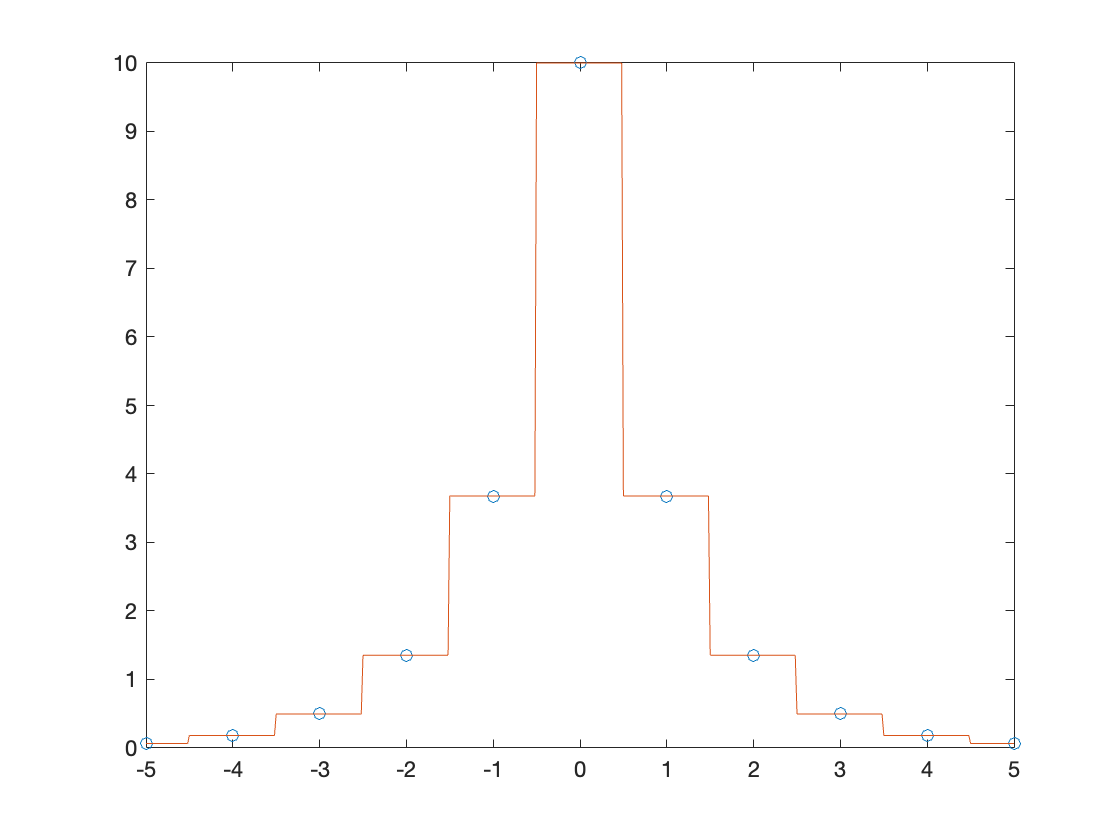

x0 = -5:1:5;
y = 10*exp(-1*abs(x0));
x = -5:0.02:5;
y1 = interp1(x0,y,x,"nearest");
plot(x0, y, 'o', x, y1);

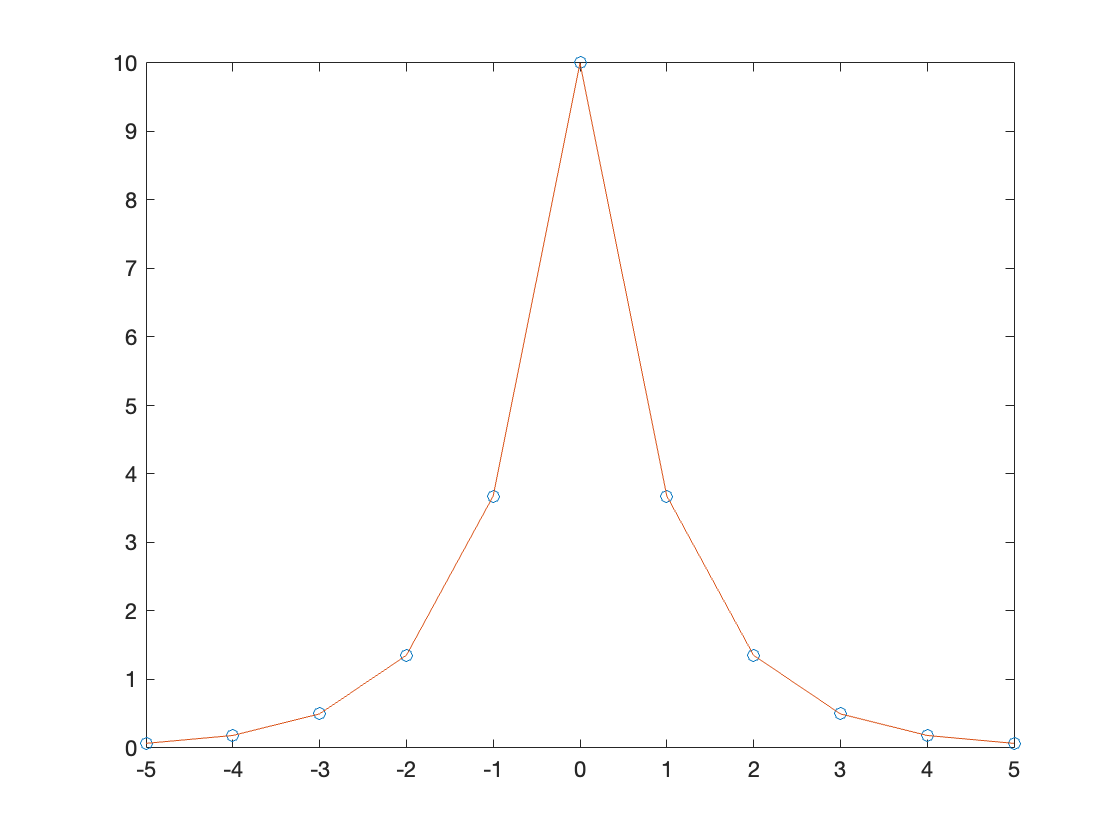

y2 = interp1(x0,y,x,"linear");
plot(x0, y, 'o', x, y2);

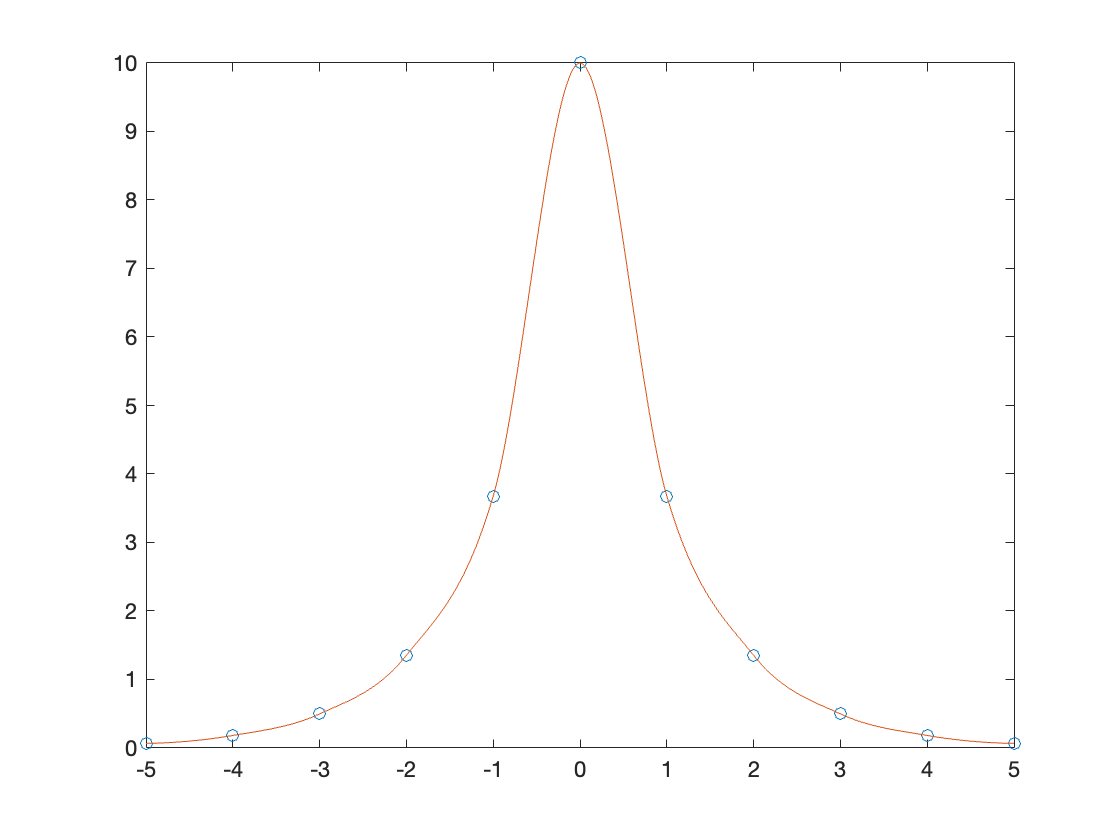

y3 = interp1(x0,y,x,"cubic");
plot(x0, y, 'o', x, y3);

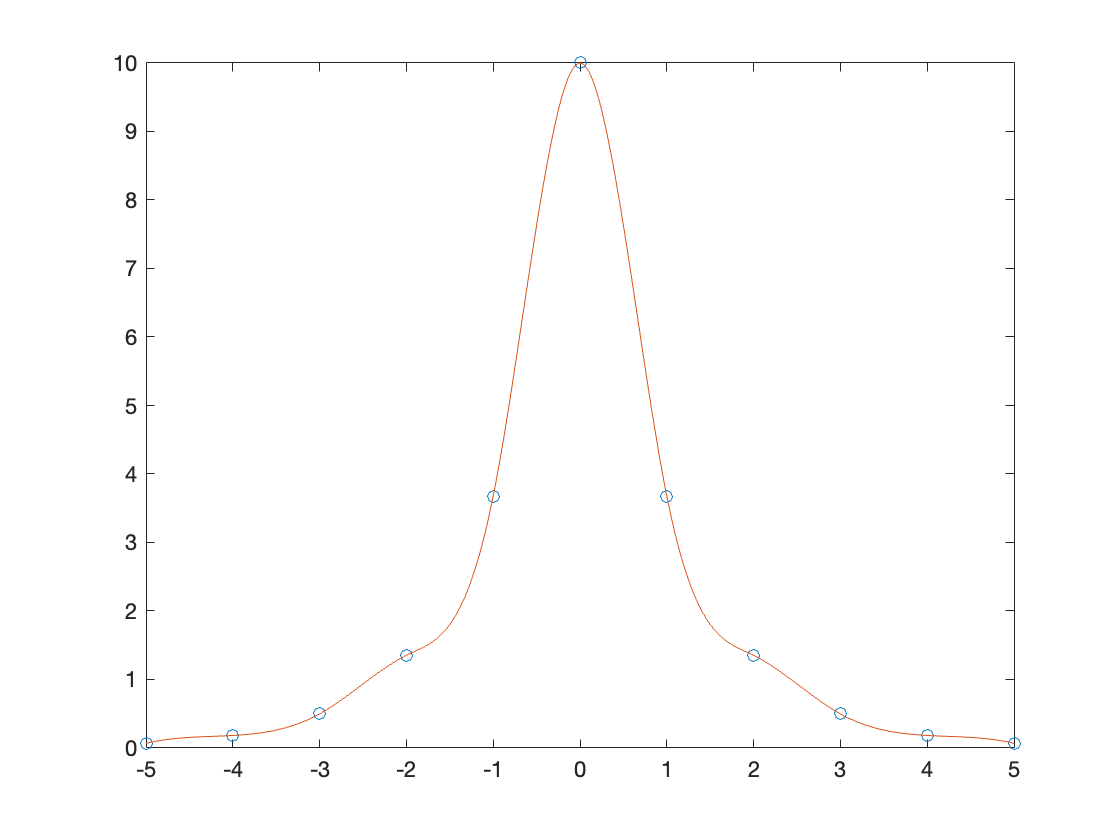

y4 = interp1(x0,y,x,"spline");
plot(x0, y, 'o', x, y4);

  4. 一个信号X=3sin(w1t)+10sin(w2t+θ)+10randn(size(t))，其中， w1=2π*20，

w2=2π*200, θ=π/4,这一信号表示被噪声污染的信号，设计程序求其DFT，并

绘图显示，说明DFT在信号检测中的作用。

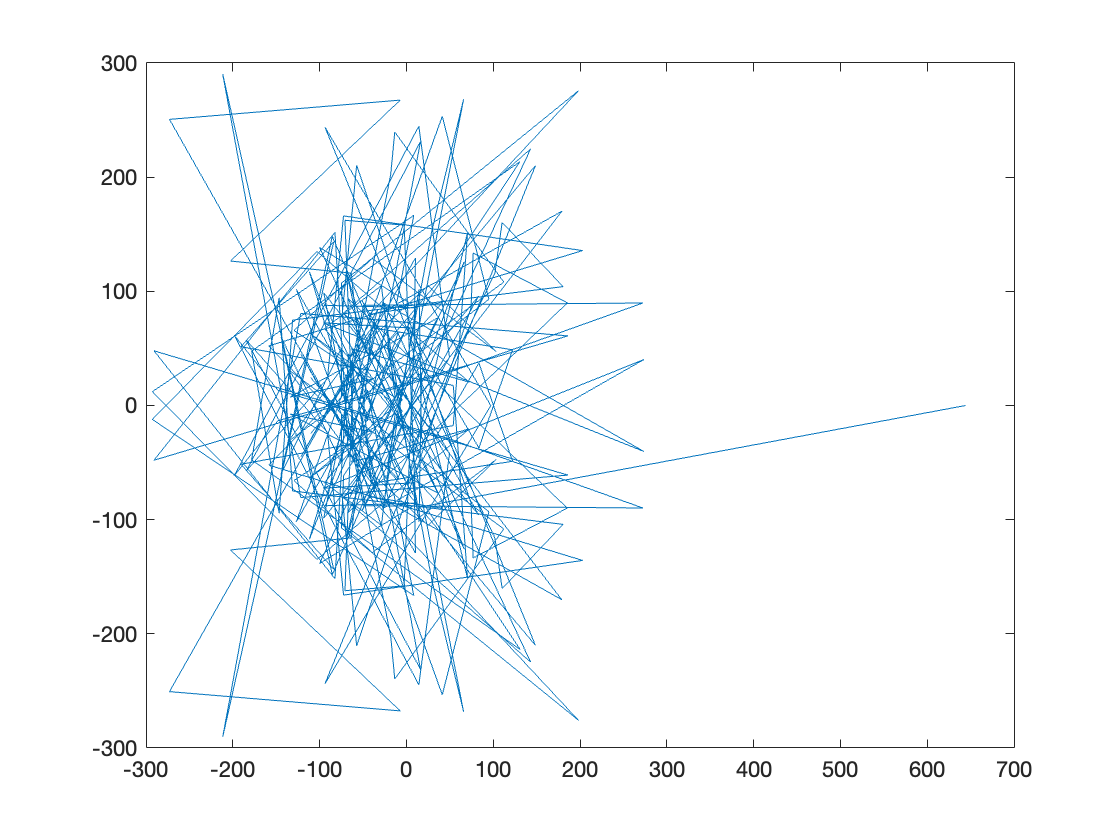

w1 = 2*pi*20;
w2 = 2*pi*200;
theta = pi/4;
t = -2*pi:0.05:2*pi;
x = 3*sin(w1*t)+10*sin(w2*t + theta) + 10*randn(size(t));
xk = fft(x);
plot(xk);

5. 已知a(x)=2x^2+3x-4 , c(x)=3x^4-2x^2+5x+6,试计算d1(x)=a(x)b(x) ,d2(x)=c(x)/a(x) , d3(x)=c(x)/b(x)的值。  

x = -10:0.05:10;
a = 2*x*x+3*x-4;
c = 3*power(x,4)-2*x*x+5*x+6;
d1 = a*b;
d2 = c/a;
d3 = c/b;

6. 求第5题中d1(x)， d2(x)， d3(x)的导数  

7. 将下列多项式进行因式分解，即计算多项式的根。

p1(x)=x^4-2x^3-3x^2+4x+2

p2(x)=x^4-7x^3+5x^2+31x-30

p3(x)=x^3-x^2-25x+25

p4(x)=-2x^5+3x^4+x^3+5x^2+8x  

8. 分别计算第7题中各多项式在1.5， 2.1和3.5的值